# 초기 작동 데이터에서 배터리 사이클 수명 예측

이 예제에서는 선형 회귀 머신러닝 지도 학습 알고리즘을 사용하여 고속 충전 리튬 이온 배터리의 잔여 사이클 수명을 예측하는 방법을 보여줍니다. 물리학 기반 모델링 접근 방식을 사용한 리튬 이온 배터리 사이클 수명 예측 과정은 동일한 제조업체에서 제조된 배터리를 사용하더라도 다양한 작동 상태와 상당한 장치 변동성으로 인해 매우 복잡합니다. 이 시나리오에서 머신러닝 기반 접근 방식은 충분한 테스트 데이터를 사용할 수 있을 때 유력한 결과를 제공합니다. 배터리 수명의 초기 단계에서 정확한 배터리 사이클 수명을 예측하면 새로운 제조 공정을 신속히 검증할 수 있습니다. 또한, 최종 사용자는 성능 저하를 식별하고 결함이 있는 배터리를 교체할 충분한 리드 타임을 확보할 수 있습니다. 이를 위해, 잔여 사이클 수명을 예측하는 데 최초 100회의 사이클을 기반으로 하는 특징만 고려되었으며 예측 오차는 약 10%로 확인되었습니다[1].

**데이터셋**

이 데이터셋은 다양한 충전 및 방전 프로파일에서 공칭 용량이 1.1Ah이고 공칭 전압이 3.3V인 리튬 이온 전지 124개에서 측정된 값을 포함합니다. 전체 데이터셋은 여기[2]에서 액세스할 수 있고 자세한 설명은 여기[1]에서 확인할 수 있습니다. 이 예제에서는 추출되는 특징과 관련된 측정값 일부를 포함하도록 데이터가 구성되었습니다. 이는 고려되는 머신러닝 모델의 성능에는 영향을 미치지 않고 다운로드 크기만 축소합니다. 훈련 데이터는 41개 전지의 측정값을 포함하고, 검증 데이터는 43개 전지의 측정값을 포함하며, 테스트 데이터는 40개 전지의 측정값을 포함합니다. 각 전지에 대한 데이터는 다음 정보를 포함하는 구조체에 저장되어 있습니다.

- 설명 데이터: 전지 바코드, 충전 정책, 사이클 수명

- 사이클별 요약 데이터: 사이클 번호, 방전 용량, 내부 저항, 충전 시간

- 각 사이클 내에서 수집된 데이터: 시간, 온도, 선형 보간 방전 용량, 선형 보간 전압

MathWorks 지원 파일 사이트에서 데이터(약 1.7GB의 대형 데이터셋)를 불러옵니다.

url = 'https://ssd.mathworks.com/supportfiles/predmaint/batterycyclelifeprediction/v1/batteryDischargeData.zip';
websave('batteryDischargeData.zip',url);
unzip('batteryDischargeData.zip')
load('batteryDischargeData');

**특징 추출**

방전 용량은 배터리 상태를 반영할 수 있는 핵심 특징으로, 방전 용량 값은 전기 자동차의 주행 범위를 나타냅니다. 훈련 데이터에 있는 전지의 최초 1,000회의 사이클에 대한 방전 용량을 플로팅하여 전지의 전체 수명에 걸친 변화를 시각화합니다.

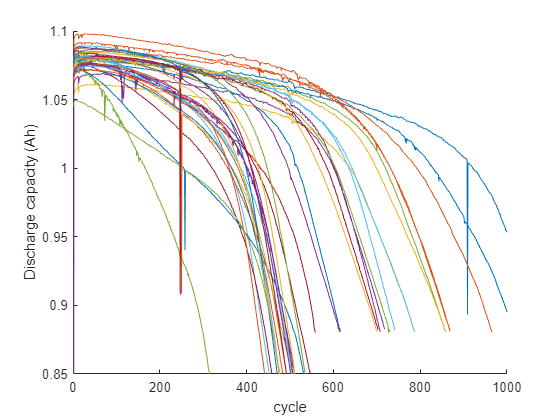

figure, hold on;
for i = 1:size(trainData,2)
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);      
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');

플롯에서 볼 수 있듯이, 전지의 수명이 다하는 시점 근처에서 용량 감소 속도가 가속화됩니다. 하지만 최초 100회의 사이클에서는 용량 감소가 무시할 수 있는 수준이므로, 그 자체로는 배터리 사이클 수명 예측에 좋은 특징은 아닙니다. 따라서, 잔여 사이클 수명을 예측하는 데 전지 내부 저항 및 온도를 포함한 추가 측정값과 함께 각 사이클의 전압 곡선을 고려하는 데이터 기반 접근 방식을 고려합니다. 주어진 사이클에 대한 전압의 함수인 방전 전압 곡선 Q(V)의 사이클 간 변화가 중요한 특징 공간입니다[1]. 특히, 사이클 간 방전 전압 곡선의 변화인 Δ*Q*(*V*)는 성능 저하 진단에 매우 효과적입니다. 따라서 100번째 사이클과 10번째 사이클 사이의 전압 함수로 방전 용량의 차이 Δ*Q*100−10(*V*)를 선택합니다.

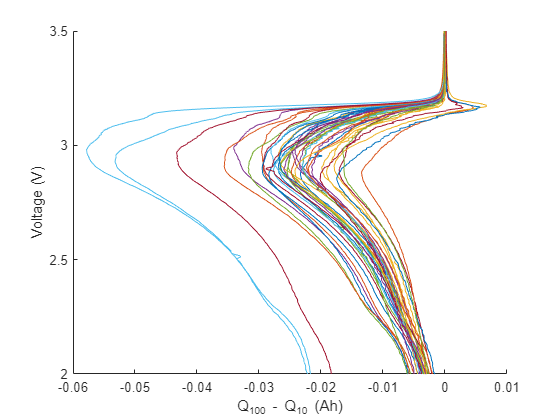

figure, hold on;
for i = 1:size(testData,2)
    plot((testData(i).cycles(100).Qdlin - testData(i).cycles(10).Qdlin), testData(i).Vdlin)   
end
ylabel('Voltage (V)'); xlabel('Q_{100} - Q_{10} (Ah)');

각 전지의 Δ*Q*100−10(*V*) 곡선을 상태 지표로 사용하여 요약 통계량을 계산합니다. 이러한 요약 통계량은 명확한 물리적 의미를 가질 필요가 없고 예측 능력만 보여주면 된다는 점을 염두에 두어야 합니다. 예를 들어, 이 로그-로그 플롯에서 보듯이 Δ*Q*100−10(*V*)의 분산과 사이클 수명 간에는 높은 상관이 있으며, 이를 통해 이 접근 방식이 유효함을 확인할 수 있습니다.

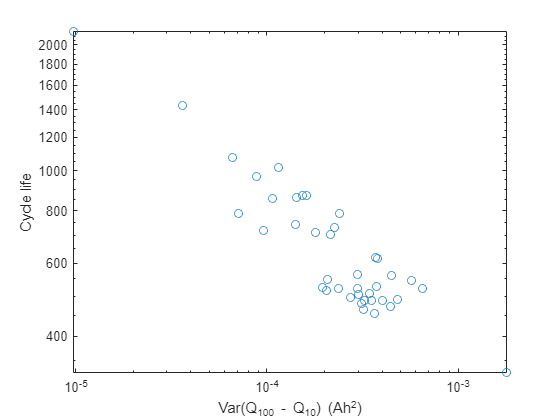

figure;
trainDataSize = size(trainData,2);
cycleLife = zeros(trainDataSize,1);
DeltaQ_var = zeros(trainDataSize,1);
for i = 1:trainDataSize
    cycleLife(i) = size(trainData(i).cycles,2) + 1;
    DeltaQ_var(i) = var(trainData(i).cycles(100).Qdlin - trainData(i).cycles(10).Qdlin);
end
loglog(DeltaQ_var,cycleLife, 'o')
ylabel('Cycle life'); xlabel('Var(Q_{100} - Q_{10}) (Ah^2)');

다음으로, 원시 측정 데이터에서 다음 특징을 추출합니다(변수 이름이 대괄호 안에 표시되어 있음)[1].

- Δ*Q*100−10(*V*) 로그 분산 [DeltaQ_var]

- Δ*Q*100−10(*V*) 로그 최솟값 [DeltaQ_min]

- 용량 감소 곡선에 대한 선형 피팅의 기울기, 사이클 2~100 [CapFadeCycle2Slope]

- 용량 감소 곡선에 대한 선형 피팅의 절편, 사이클 2~100 [CapFadeCycle2Intercept]

- 사이클 2에서의 방전 용량 [Qd2]

- 최초 5회 사이클에 대한 평균 충전 시간 [AvgChargeTime]

- 최소 내부 저항, 사이클 2~100 [MinIR]

- 사이클 2와 사이클 100 사이의 내부 저항 차이 [IRDiff2And100]

`helperGetFeatures` 함수는 원시 측정 데이터를 받아 위에 나열된 특징을 계산합니다. 이 함수는 테이블에 특징을 포함하는 `XTrain`과 예상 잔여 사이클 수명을 포함하는 `yTrain`을 반환합니다.

[XTrain,yTrain] = helperGetFeatures(trainData);
head(XTrain)

ans = 8×8 table
    DeltaQ_var    DeltaQ_min    CapFadeCycle2Slope    CapFadeCycle2Intercept     Qd2      AvgChargeTime     MinIR      IRDiff2And100
    __________    __________    __________________    ______________________    ______    _____________    ________    _____________

     -5.0839       -1.9638          6.4708e-06                1.0809            1.0753       13.409        0.016764     -3.3898e-05 
     -4.3754       -1.6928          1.6313e-05                1.0841            1.0797       12.025        0.016098      4.4186e-05 
     -4.1464       -1.5889          8.1708e-06                  1.08            1.0761       10.968        0.015923     -0.00012443 
     -3.8068       -1.4216          -8.491e-06                1.0974            1.0939       10.025        0.016083     -3.7309e-05 
     -4.1181       -1.6089          2.2859e-05                1.0589            1.0538       11.669        0.015963     -0.00030445 
     -4.0225       -1.5407          2.5969e-05      

**모델 개발: 신축망 정규화를 사용한 선형 회귀**

정규화된 선형 모델을 사용하여 전지의 잔여 사이클 수명을 예측합니다. 선형 모델은 계산 비용은 낮지만 해석 가능성은 높습니다. 선형 모델의 형태는 다음과 같습니다.

*y**i*=**w***T***x***i*+*β*

여기서 *y**i*는 전지 *i*에 대한 사이클 횟수, **x***i*는 전지 *i*에 대한 *p*차원 특징 벡터, **w**는 *p*차원 모델 계수 벡터, *β*는 스칼라 절편입니다. 선형 모델은 특징 사이의 높은 상관을 다루기 위해 신축망을 사용하여 정규화됩니다. 엄밀히 0에서 1 사이에 있는 *α*와 음수가 아닌 정규화 계수 *λ*에 대해 신축망은 다음과 같은 문제를 풉니다.

여기서 입니다. 신축망은 *α*가 0에 가까울 때 능형 회귀에 접근하고 *α*=1일 때 Lasso 정규화와 동일합니다. 훈련 데이터는 하이퍼파라미터 *α*와 *λ*를 선택하고 계수 **w**의 값을 결정하는 데 사용됩니다. `lasso` 함수는 피팅된 최소 제곱 회귀 계수와 모델의 피팅에 대한 정보를 각각 *α*와 *λ* 값에 대한 출력값으로 반환합니다. `lasso` 함수는 *λ* 파라미터에 대해 값으로 구성된 벡터를 받습니다. 따라서 *α*의 각 값에 대해 가장 낮은 RMSE 값을 산출하는 모델 계수 **w**와 *λ*가 계산됩니다. [1]에 제안된 대로, 교차 검증을 위해 1회의 몬테카를로 반복과 함께 4겹 교차 검증을 사용합니다.

rng("default")

alphaVec = 0.01:0.1:1;
lambdaVec = 0:0.01:1;
MCReps = 1;
cvFold = 4;

rmseList = zeros(length(alphaVec),1);
minLambdaMSE = zeros(length(alphaVec),1);
wModelList = cell(1,length(alphaVec));
betaVec = cell(1,length(alphaVec));

for i=1:length(alphaVec)
    [coefficients,fitInfo] = ...
        lasso(XTrain.Variables,yTrain,'Alpha',alphaVec(i),'CV',cvFold,'MCReps',MCReps,'Lambda',lambdaVec);
    wModelList{i} = coefficients(:,fitInfo.IndexMinMSE);
    betaVec{i} = fitInfo.Intercept(fitInfo.IndexMinMSE);       
    indexMinMSE = fitInfo.IndexMinMSE;
    rmseList(i) = sqrt(fitInfo.MSE(indexMinMSE));    
    minLambdaMSE(i) = fitInfo.LambdaMinMSE;    
end

피팅된 모델을 견고하게 만들기 위해 검증 데이터를 사용하여 *α*와 *λ* 하이퍼파라미터의 최종 값을 선택합니다. 이를 위해 훈련 데이터를 사용하여 계산된 네 개의 가장 낮은 RMSE 값에 해당하는 계수를 선택합니다.

numVal = 4;
[out,idx] = sort(rmseList);
val = out(1:numVal);
index = idx(1:numVal);

alpha = alphaVec(index);
lambda = minLambdaMSE(index);
wModel = wModelList(index);
beta = betaVec(index);

각 계수 집합에 대해, 검증 데이터에 대한 예측 값과 RMSE를 계산합니다.

[XVal,yVal] = helperGetFeatures(valData);
rmseValModel = zeros(numVal);
for valList = 1:numVal   
   yPredVal = (XVal.Variables*wModel{valList} + beta{valList});
   rmseValModel(valList) = sqrt(mean((yPredVal-yVal).^2));
end

검증 데이터를 사용할 때는 RMSE가 최소인 모델을 선택합니다. 훈련 데이터에 대해 가장 낮은 RMSE 값을 보여주는 모델이 검증 데이터에 대해서도 가장 낮은 RMSE 값을 보여주지는 않습니다. 검증 데이터를 사용하면 모델의 강인성이 향상됩니다.

[rmseMinVal,idx] = min(rmseValModel);
wModelFinal = wModel{idx};
betaFinal = beta{idx};

**훈련된 모델의 성능 평가**

테스트 데이터는 40개 전지에 해당하는 측정값을 포함합니다. `testData`에서 특징과 그에 대응하는 응답을 추출합니다. 훈련된 모델을 사용하여 `testData`에서 각 전지의 잔여 사이클 수명을 예측합니다

[XTest,yTest] = helperGetFeatures(testData);
yPredTest = (XTest.Variables*wModelFinal + betaFinal);

테스트 데이터에 대해 예측된 사이클 수명과 실제 사이클 수명 간의 관계를 보여주는 플롯을 시각화합니다.

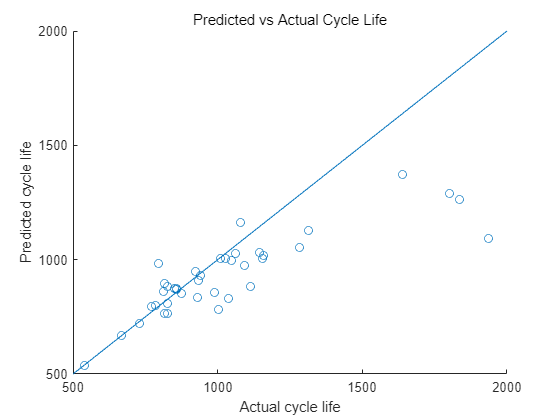

figure;
scatter(yTest,yPredTest)
hold on;
refline(1, 0);
title('Predicted vs Actual Cycle Life')
ylabel('Predicted cycle life');
xlabel('Actual cycle life');

이상적으로는, 위에 표시된 플롯의 모든 점이 대각선에 가까워야 합니다. 위에 표시된 플롯에서는 잔여 사이클 수명이 500~1,200회 사이클 사이일 때 훈련된 모델의 성능이 좋은 것으로 보입니다. 1,200회 사이클을 넘으면 모델 성능이 저하됩니다. 이 모델은 이 영역에서 잔여 사이클 수명을 일관되게 과소평가합니다. 이는 주로 테스트 및 검증 데이터 세트가 총 수명이 약 1,000회 사이클인 전지를 훨씬 더 많이 포함하기 때문입니다.

예측된 잔여 사이클 수명의 RMSE를 계산합니다.

errTest = (yPredTest-yTest);
rmseTestModel = sqrt(mean(errTest.^2))

rmseTestModel = 211.6148

성능 평가에 고려되는 또 다른 메트릭은 다음으로 정의되는 평균 백분율 오차입니다[1].


$$\% err = \frac{1}{n} \Sigma_{i=1}^{n} \frac{\vert y_i - \hat{y}_i \vert}{y_i} \times 100$$


n = numel(yTest);
nr = abs(yTest - yPredTest);
errVal = (1/n)*sum(nr./yTest)*100

errVal = 9.9817

**결론**

이 예제에서는 최초 100회 사이클에서 측정한 값을 기준으로만 배터리 사이클 수명을 예측하기 위해 신축망 정규화를 사용한 선형 회귀 모델을 사용하는 방법을 보여주었습니다. 사용자 지정 특징을 원시 측정 데이터에서 추출하고 훈련 데이터를 사용하여 신축망 정규화를 사용한 선형 회귀 모델을 피팅했습니다. 그런 다음, 검증 데이터셋을 사용해 하이퍼파라미터를 선택했습니다. 이 모델은 성능 평가를 위해 테스트 데이터에 사용되었습니다. 최초 100회 사이클에 대한 측정값만 사용할 때, 테스트 데이터 세트에 포함된 전지의 잔여 사이클 수명 예측에 대한 RMSE는 211.6이고 평균 백분율 오차는 9.98%입니다.

## ***참고 문헌***

[1] Severson, K.A., Attia, P.M., Jin, N. *et al.* "Data-driven prediction of battery cycle life before capacity degradation." *Nat Energy* **4, **383–391 (2019). https://doi.org/10.1038/s41560-019-0356-8

[2] [https://data.matr.io/1/](https://data.matr.io/1/) 

## **지원 함수**

function [xTable, y] = helperGetFeatures(batch)
% HELPERGETFEATURES function accepts the raw measurement data and computes
% the following feature:
%
% Q_{100-10}(V) variance [DeltaQ_var]
% Q_{100-10}(V) minimum [DeltaQ_min]
% Slope of linear fit to the capacity fade curve cycles 2 to 100 [CapFadeCycle2Slope]
% Intercept of linear fit to capacity fade curve, cycles 2 to 100 [CapFadeCycle2Intercept]
% Discharge capacity at cycle 2 [Qd2]
% Average charge time over first 5 cycles [AvgChargeTime]
% Minimum Internal Resistance, cycles 2 to 100 [MinIR]
% Internal Resistance difference between cycles 2 and 100 [IRDiff2And100]

N = size(batch,2); % Number of batteries

% Preallocation of variables
y = zeros(N, 1);
DeltaQ_var = zeros(N,1);
DeltaQ_min = zeros(N,1);
CapFadeCycle2Slope = zeros(N,1);
CapFadeCycle2Intercept = zeros(N,1);
Qd2 = zeros(N,1);
AvgChargeTime = zeros(N,1);
IntegralTemp = zeros(N,1);
MinIR = zeros(N,1);
IRDiff2And100 = zeros(N,1);

for i = 1:N
    % cycle life
    y(i,1) = size(batch(i).cycles,2) + 1;
    
    % Identify cycles with time gaps
    numCycles = size(batch(i).cycles, 2);
    timeGapCycleIdx = [];
    jBadCycle = 0;
    for jCycle = 2: numCycles
        dt = diff(batch(i).cycles(jCycle).t);
        if max(dt) > 5*mean(dt)
            jBadCycle = jBadCycle + 1;
            timeGapCycleIdx(jBadCycle) = jCycle;
        end
    end
    
    % Remove cycles with time gaps
    batch(i).cycles(timeGapCycleIdx) = [];
    batch(i).summary.QDischarge(timeGapCycleIdx) = [];
    batch(i).summary.IR(timeGapCycleIdx) = [];
    batch(i).summary.chargetime(timeGapCycleIdx) = [];
    
    % compute Q_100_10 stats
    DeltaQ = batch(i).cycles(100).Qdlin - batch(i).cycles(10).Qdlin;
    DeltaQ_var(i) = log10(abs(var(DeltaQ)));
    DeltaQ_min(i) = log10(abs(min(DeltaQ)));
    
    % Slope and intercept of linear fit for capacity fade curve from cycle
    % 2 to cycle 100
    coeff2 = polyfit(batch(i).summary.cycle(2:100), batch(i).summary.QDischarge(2:100),1);
    CapFadeCycle2Slope(i) = coeff2(1);
    CapFadeCycle2Intercept(i) = coeff2(2);
    
    %  Discharge capacity at cycle 2
    Qd2(i) = batch(i).summary.QDischarge(2);
    
    % Avg charge time, first 5 cycles (2 to 6)
    AvgChargeTime(i) = mean(batch(i).summary.chargetime(2:6));
    
    % Integral of temperature from cycles 2 to 100
    tempIntT = 0;
    for jCycle = 2:100
        tempIntT = tempIntT + trapz(batch(i).cycles(jCycle).t, batch(i).cycles(jCycle).T);
    end
    IntegralTemp(i) = tempIntT;
    
    % Minimum internal resistance, cycles 2 to 100
    temp = batch(i).summary.IR(2:100);
    MinIR(i) = min(temp(temp~=0));
    IRDiff2And100(i) = batch(i).summary.IR(100) - batch(i).summary.IR(2);
end

xTable = table(DeltaQ_var, DeltaQ_min, ...
    CapFadeCycle2Slope, CapFadeCycle2Intercept,...
    Qd2, AvgChargeTime, MinIR, IRDiff2And100);

end

*Copyright 2020 The MathWorks, Inc.*